# Atividade 05_02

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Filtro da média (funções imfilter e fspecial)

Usar as funções imfilter e fspecial para aplicar o filtro da média (box filter) nas imagens de RM b5s.40.bmp e b5s.100. Utilize duas dimensões diferentes de janela à sua escolha, e observe como o tamanho da janela atua na intensidade da suavização. Mostre as imagens de entrada e de saída (in vs. out).

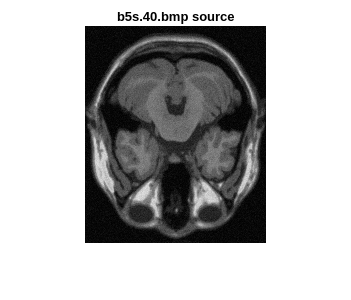

img1 = imread("b5s.40.bmp");
img2 = imread("b5s.100.bmp");

kernel1 = fspecial("average", [3 3]);
kernel2 = fspecial("average", [7 7]);

img1Kernel1 = imfilter(img1, kernel1);
img1Kernel2 = imfilter(img1, kernel2);

img2Kernel1 = imfilter(img2, kernel1);
img2Kernel2 = imfilter(img2, kernel2);

figure, imshow(img1)
title("b5s.40.bmp source")

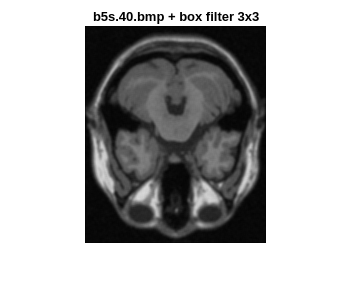


figure, imshow(img1Kernel1)
title("b5s.40.bmp + box filter 3x3")

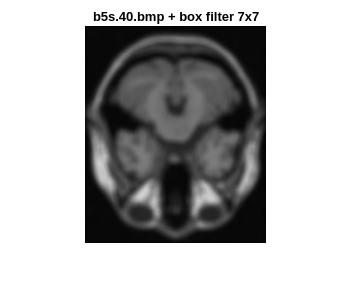


figure, imshow(img1Kernel2)
title("b5s.40.bmp + box filter 7x7")

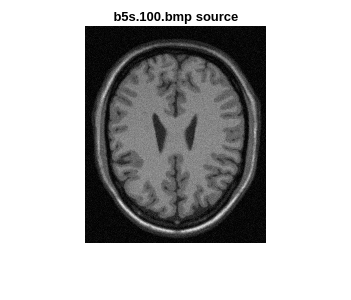


figure, imshow(img2)
title("b5s.100.bmp source")

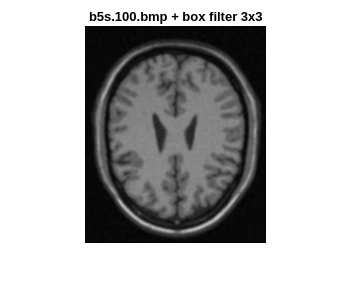


figure, imshow(img2Kernel1)
title("b5s.100.bmp + box filter 3x3")

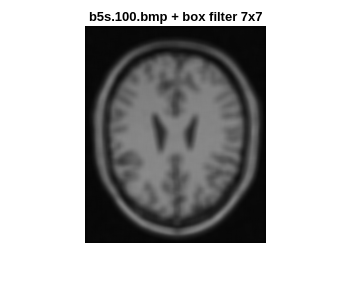


figure, imshow(img2Kernel2)
title("b5s.100.bmp + box filter 7x7")